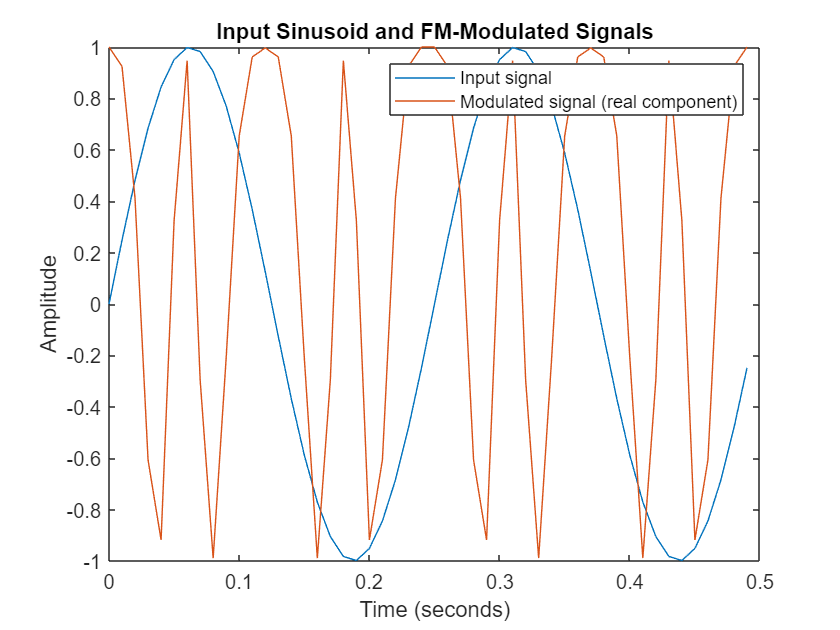

fs = 100;  % Sample rate (Hz)
ts = 1/fs; % Sample period (s)
fd = 25;   % Frequency deviation (Hz)
t = (0:ts:0.5-ts)';
x = sin(2*pi*4*t);
fmmodulator = comm.FMModulator( ...
    'SampleRate',fs, ...
    'FrequencyDeviation',fd);
fmdemodulator = comm.FMDemodulator(fmmodulator);
y = fmmodulator(x);
plot(t,[x real(y)])
title('Input Sinusoid and FM-Modulated Signals')
xlabel('Time (seconds)'); ylabel('Amplitude')
legend('Input signal','Modulated signal (real component)')

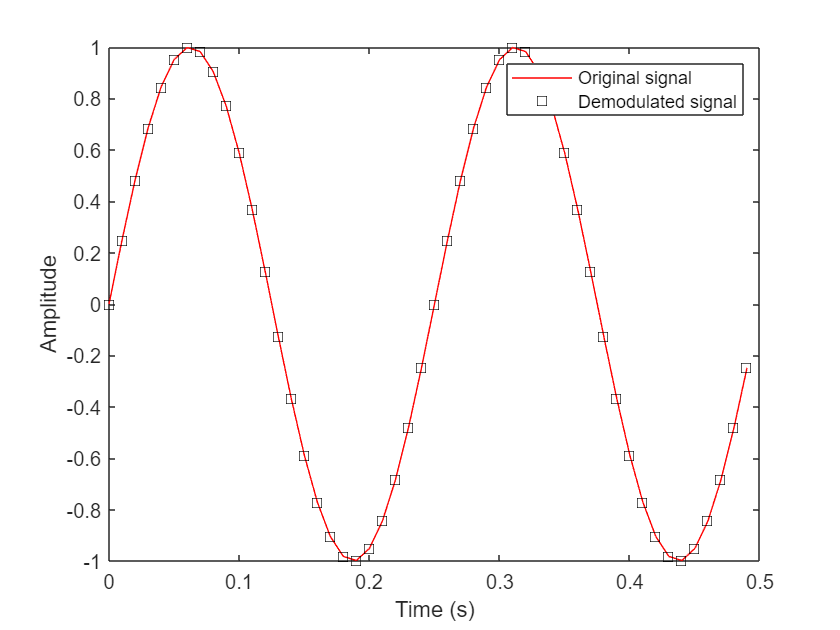

z = fmdemodulator(y);
plot(t,x,'r',t,z,'ks')
legend('Original signal','Demodulated signal')
xlabel('Time (s)')
ylabel('Amplitude')